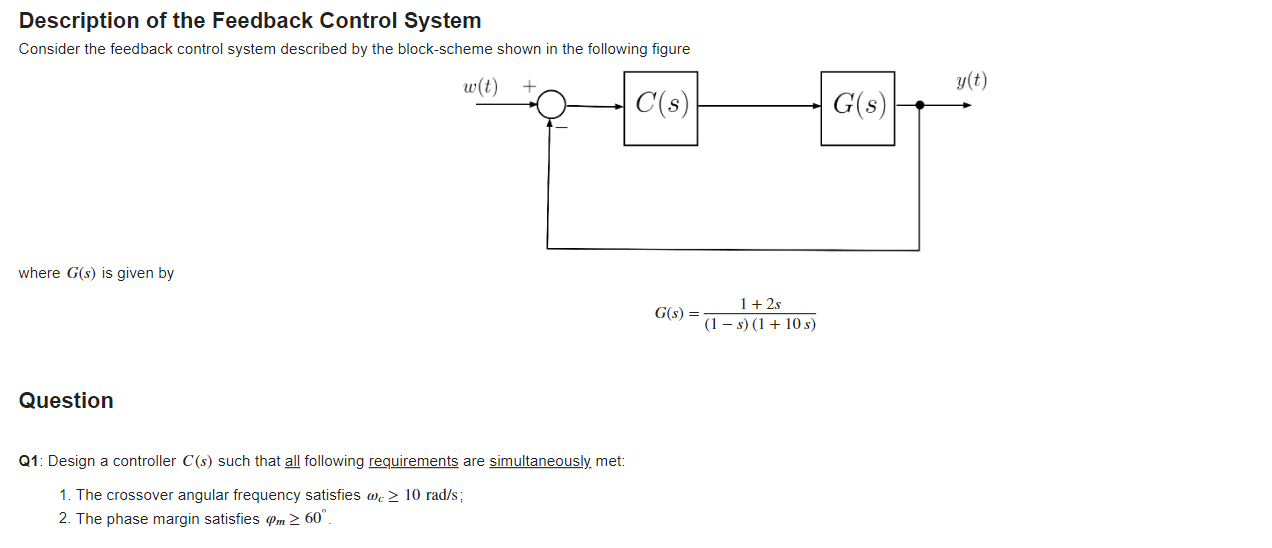

**ANALISI PRELIMINARE**

Dato che il sistema opne-loop è instabile, procediamo ad analizzare il sistema utilizzando un **dual-loop control scheme**, come riportato in figura

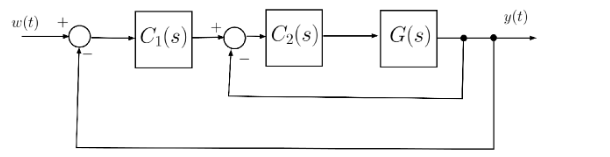

Il design del controllore $C(s)$ viene eseguito seguendo questi passi:

- Il controllore $C_2(s)$ viene utilizzato in modo tale che la funzione $F_2(s)$ sia asintoticamente stabile

- Il controllore $C_1(s)$ viene utilizzato per soddisfare gli altri requisiti

Prima di tutto, dobbiamo rendere la FdT asintoticamente stabile, poniamo


$$C_2(s) = \mu_2 \ \ \ , \ \ \ \; \mu_2 \in \mathbb{R}$$


Applicando il criterio di **Routh-Hurwitz **troviamo per quali valori di $\mu_2$ il sistema è asintoticamente stabile


$$C_2(s) = \mu_2 \; \Longrightarrow \; L_2(s) = \mu_2\,\frac{(1+2s)}{(1-s)\,(1+10s)} \; \Longrightarrow \; 1+L_2(s)=0 \,\longleftrightarrow\,
-10s^2+\left(9+2\,\mu_2\right)s+(\mu_2+1) =0
$$


Quindi, otteniamo le seguenti condizioni:

- se $\mu_2<-\frac{9}{2}$  allora il sistema è asintoticamente stabile

- se $\mu_2 \in \left(-\frac{19}{2}-\sqrt{60}\;,\quad -\frac{9}{2}\right)$,i poli closed-loop sono complessi coniugati

- se $\mu_2 < -\frac{19}{2}-\sqrt{60}$, i poli closed-loop sono reali e distinti

Una volta ottenuto questo, fissiamo $\mu_2 = -10$

Scegliendo $C_2(s) = -10$ allora la FdT è asintoticamente stabile e la $F_2(s)$ risulta


$$F_2(s) = \frac{C_2(s) G(s)}{1+C_2(s)\,G(s)} = \frac{1+2s}{\frac{9}{10}+\frac{11}{10}s+s^2}$$


A questo punto, ci resta solamente da progettare il controllore $C_1
(s)$ in modo da rispettare i requisiti Q1.1 e Q1.2

Il controllore $C_1(s)$ è della forma $C_1(s) = \mu_1$

FIssando la pulsazione critica $\omega_c = 15$ rad/s otteniamo un buon margine di fase,


$$\bar \omega = 15\;\text{rad/s} \quad \Longrightarrow \quad \arg L_1(j \bar \omega) = \arg L_1(j 15) \approx -88^{\degree} \quad \Longrightarrow \quad \varphi_m \approx +92^{\degree}$$


L'ultimo step è quello di determinare il valore di $\mu_1$ per avere il valore del controllore finale


$$\left\vert L_1(j \,15)\right\vert = 1 \quad \Longrightarrow \quad 
\hat{\mu}_1 \, \frac{\left\vert 1+j\,30\right\vert}{\left\vert \frac{9}{10}+\frac{11}{10}\cdot j15 -15^2\right\vert} = 1 \quad
\Longrightarrow \quad \hat{\mu}_1  \approx 7.49$$


Verifichiamo i risultati ottenuti mediante il **Control System Designer App**

s = tf('s');

% Define the transfer function G(s)

Gs = (1+2*s)/((1-s)*(1+10*s))

Gs =
 
      -2 s - 1
  ----------------
  10 s^2 - 9 s - 1
 
Continuous-time transfer function.
Model Properties



% Define the controller C(s) = C1(s)*C2(s)

C1 = -10;
C2 = 7.5;

Cs = C1*C2

Cs = -75


controlSystemDesigner(Gs,Cs)
